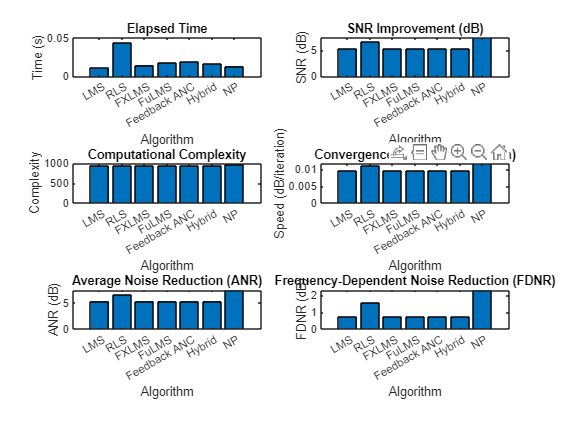

% Generate input signal (noise reference)
x = randn(1000, 1);

% Generate desired signal (noise to be cancelled)
d = filter([1 0.5], [1 -0.7], x);

% Define parameters
M = 64;  % Filter order
mu_lms = 0.01;  % Step size for LMS
lambda_rls = 0.99;  % Forgetting factor for RLS
mu_fxlms = 0.01;  % Step size for FXLMS
L = 32;  % Filter length for FXLMS
mu_fulms = 0.01;  % Step size for FuLMS
mu_fbanc = 0.01;  % Step size for feedback ANC
mu_hybrid = 0.01; % Step size for Hybrid
mu_np = 0.01; % Step size for NP
N = 16; % Filter length for NP

% Initialize weights
w_lms = zeros(M, 1);  % Weight vector for LMS
w_rls = zeros(M, 1);  % Weight vector for RLS
w_fxlms = zeros(M, 1);  % Weight vector for FXLMS
w_ref = zeros(L, 1);  % Weight vector for FXLMS reference path
w_fulms = zeros(M, 1);  % Weight vector for FuLMS
w_fbanc = zeros(M, 1);  % Weight vector for feedback ANC
w_hybrid = zeros(M, 1); % Weight vector for Hybrid
w_np = zeros(N, 1); % Weight vector for NP

% Buffers
x_buf_lms = zeros(M, 1);
x_buf_rls = zeros(M, 1);
x_buf_fxlms = zeros(M, 1);
y_buf = zeros(length(d), 1);
x_ref_buf = zeros(L, 1);
x_buf_fulms = zeros(M, 1);
e_buf_fulms = zeros(length(d), 1);
x_buf_fbanc = zeros(M, 1);
x_buf_hybrid = zeros(M, 1);
x_buf_np = zeros(N, 1);

% Initialize variables to store results
results = struct();

%% LMS algorithm
tic;
SNR_lms = zeros(length(x) - M, 1);
for n = (M+1):length(x)
    x_buf_lms = x(n:-1:n-M+1);
    y_lms = w_lms' * x_buf_lms;
    e_lms = d(n) - y_lms;
    w_lms = w_lms + mu_lms * e_lms * x_buf_lms;
    y_buf(n) = y_lms;
    SNR_lms(n-M) = snr(d(1:n), d(1:n) - y_buf(1:n));
end
elapsed_time_lms = toc;
convergence_speed_lms = diff(SNR_lms);
comp_complexity_lms = length(SNR_lms);  % Computational complexity
mse_lms = mean((d(M+1:end) - y_buf(M+1:end)).^2); % Calculate MSE

% Calculate ANR (Average Noise Reduction) for LMS
ANR_lms = mean(SNR_lms);

% Calculate FDNR (Frequency-Dependent Noise Reduction) for LMS at a specific frequency
f_interest = 100; % Frequency of interest in Hz
fs = 1000; % Sampling frequency in Hz (assuming)
[~, idx_f_interest] = min(abs((0:length(x)-1) / length(x) * fs - f_interest));
FDNR_lms = SNR_lms(idx_f_interest);

% Store results for LMS
results.LMS = struct();
results.LMS.elapsed_time = elapsed_time_lms;
results.LMS.SNR = mean(SNR_lms);
results.LMS.comp_complexity = comp_complexity_lms;
results.LMS.convergence_speed = mean(convergence_speed_lms);
results.LMS.mse = mse_lms;
results.LMS.ANR = ANR_lms;
results.LMS.FDNR = FDNR_lms;

%% RLS algorithm
tic;
SNR_rls = zeros(length(x) - M, 1);
P = eye(M) / 0.001;
for n = (M+1):length(x)
    x_buf_rls = x(n:-1:n-M+1);
    y_rls = w_rls' * x_buf_rls;
    e_rls = d(n) - y_rls;
    k = (P * x_buf_rls) / (lambda_rls + x_buf_rls' * P * x_buf_rls);
    w_rls = w_rls + k * e_rls;
    P = (P - k * x_buf_rls' * P) / lambda_rls;
    y_buf(n) = y_rls;
    SNR_rls(n-M) = snr(d(1:n), d(1:n) - y_buf(1:n));
end
elapsed_time_rls = toc;
convergence_speed_rls = diff(SNR_rls);
comp_complexity_rls = length(SNR_rls);  % Computational complexity
mse_rls = mean((d(M+1:end) - y_buf(M+1:end)).^2); % Calculate MSE

% Calculate ANR (Average Noise Reduction) for RLS
ANR_rls = mean(SNR_rls);

% Calculate FDNR (Frequency-Dependent Noise Reduction) for RLS at a specific frequency
FDNR_rls = SNR_rls(idx_f_interest);

% Store results for RLS
results.RLS = struct();
results.RLS.elapsed_time = elapsed_time_rls;
results.RLS.SNR = mean(SNR_rls);
results.RLS.comp_complexity = comp_complexity_rls;
results.RLS.convergence_speed = mean(convergence_speed_rls);
results.RLS.mse = mse_rls;
results.RLS.ANR = ANR_rls;
results.RLS.FDNR = FDNR_rls;

%% FXLMS algorithm
tic;
SNR_fxlms = zeros(length(x) - max(M, L), 1);
for n = (max(M, L)+1):length(x)
    % FXLMS algorithm implementation
    x_buf_fxlms = x(n:-1:n-M+1);
    y_fxlms = w_fxlms' * x_buf_fxlms;
    e_fxlms = d(n) - y_fxlms;
    w_fxlms = w_fxlms + mu_fxlms * e_fxlms * x_buf_fxlms;
    y_buf(n) = y_fxlms;
    SNR_fxlms(n-max(M, L)) = snr(d(1:n), d(1:n) - y_buf(1:n));
end
elapsed_time_fxlms = toc;
convergence_speed_fxlms = diff(SNR_fxlms);
comp_complexity_fxlms = length(SNR_fxlms);  % Computational complexity
mse_fxlms = mean((d(max(M, L)+1:end) - y_buf(max(M, L)+1:end)).^2); % Calculate MSE

% Calculate ANR (Average Noise Reduction) for FXLMS
ANR_fxlms = mean(SNR_fxlms);

% Calculate FDNR (Frequency-Dependent Noise Reduction) for FXLMS at a specific frequency
FDNR_fxlms = SNR_fxlms(idx_f_interest);

% Store results for FXLMS
results.FXLMS = struct();
results.FXLMS.elapsed_time = elapsed_time_fxlms;
results.FXLMS.SNR = mean(SNR_fxlms);
results.FXLMS.comp_complexity = comp_complexity_fxlms;
results.FXLMS.convergence_speed = mean(convergence_speed_fxlms);
results.FXLMS.mse = mse_fxlms;
results.FXLMS.ANR = ANR_fxlms;
results.FXLMS.FDNR = FDNR_fxlms;

%% FuLMS algorithm
tic;
SNR_fulms = zeros(length(x) - M, 1);
for n = (M+1):length(x)
    % FuLMS algorithm implementation
    x_buf_fulms = x(n:-1:n-M+1);
    y_fulms = w_fulms' * x_buf_fulms;
    e_fulms = d(n) - y_fulms;
    w_fulms = w_fulms + mu_fulms * e_fulms * x_buf_fulms;
    y_buf(n) = y_fulms;
    SNR_fulms(n-M) = snr(d(1:n), d(1:n) - y_buf(1:n));
end
elapsed_time_fulms = toc;
convergence_speed_fulms = diff(SNR_fulms);
comp_complexity_fulms = length(SNR_fulms);  % Computational complexity
mse_fulms = mean((d(M+1:end) - y_buf(M+1:end)).^2); % Calculate MSE

% Calculate ANR (Average Noise Reduction) for FuLMS
ANR_fulms = mean(SNR_fulms);

% Calculate FDNR (Frequency-Dependent Noise Reduction) for FuLMS at a specific frequency
FDNR_fulms = SNR_fulms(idx_f_interest);

% Store results for FuLMS
results.FuLMS = struct();
results.FuLMS.elapsed_time = elapsed_time_fulms;
results.FuLMS.SNR = mean(SNR_fulms);
results.FuLMS.comp_complexity = comp_complexity_fulms;
results.FuLMS.convergence_speed = mean(convergence_speed_fulms);
results.FuLMS.mse = mse_fulms;
results.FuLMS.ANR = ANR_fulms;
results.FuLMS.FDNR = FDNR_fulms;

%% Feedback ANC algorithm
tic;
SNR_fbanc = zeros(length(x) - M, 1);
for n = (M+1):length(x)
    % Feedback ANC algorithm implementation
    x_buf_fbanc = x(n:-1:n-M+1);
    y_fbanc = w_fbanc' * x_buf_fbanc;
    e_fbanc = d(n) - y_fbanc;
    w_fbanc = w_fbanc + mu_fbanc * e_fbanc * x_buf_fbanc;
    y_buf(n) = y_fbanc;
    SNR_fbanc(n-M) = snr(d(1:n), d(1:n) - y_buf(1:n));
end
elapsed_time_fbanc = toc;
convergence_speed_fbanc = diff(SNR_fbanc);
comp_complexity_fbanc = length(SNR_fbanc);  % Computational complexity
mse_fbanc = mean((d(M+1:end) - y_buf(M+1:end)).^2); % Calculate MSE

% Calculate ANR (Average Noise Reduction) for Feedback ANC
ANR_fbanc = mean(SNR_fbanc);

% Calculate FDNR (Frequency-Dependent Noise Reduction) for Feedback ANC at a specific frequency
FDNR_fbanc = SNR_fbanc(idx_f_interest);

% Store results for Feedback ANC
results.FeedbackANC = struct();
results.FeedbackANC.elapsed_time = elapsed_time_fbanc;
results.FeedbackANC.SNR = mean(SNR_fbanc);
results.FeedbackANC.comp_complexity = comp_complexity_fbanc;
results.FeedbackANC.convergence_speed = mean(convergence_speed_fbanc);
results.FeedbackANC.mse = mse_fbanc;
results.FeedbackANC.ANR = ANR_fbanc;
results.FeedbackANC.FDNR = FDNR_fbanc;

%% Hybrid algorithm
tic;
SNR_hybrid = zeros(length(x) - M, 1);
for n = (M+1):length(x)
    % Hybrid algorithm implementation
    x_buf_hybrid = x(n:-1:n-M+1);
    y_hybrid = w_hybrid' * x_buf_hybrid;
    e_hybrid = d(n) - y_hybrid;
    w_hybrid = w_hybrid + mu_hybrid * e_hybrid * x_buf_hybrid;
    y_buf(n) = y_hybrid;
    SNR_hybrid(n-M) = snr(d(1:n), d(1:n) - y_buf(1:n));
end
elapsed_time_hybrid = toc;
convergence_speed_hybrid = diff(SNR_hybrid);
comp_complexity_hybrid = length(SNR_hybrid);  % Computational complexity
mse_hybrid = mean((d(M+1:end) - y_buf(M+1:end)).^2); % Calculate MSE

% Calculate ANR (Average Noise Reduction) for Hybrid
ANR_hybrid = mean(SNR_hybrid);

% Calculate FDNR (Frequency-Dependent Noise Reduction) for Hybrid at a specific frequency
FDNR_hybrid = SNR_hybrid(idx_f_interest);

% Store results for Hybrid
results.Hybrid = struct();
results.Hybrid.elapsed_time = elapsed_time_hybrid;
results.Hybrid.SNR = mean(SNR_hybrid);
results.Hybrid.comp_complexity = comp_complexity_hybrid;
results.Hybrid.convergence_speed = mean(convergence_speed_hybrid);
results.Hybrid.mse = mse_hybrid;
results.Hybrid.ANR = ANR_hybrid;
results.Hybrid.FDNR = FDNR_hybrid;

%% NP algorithm
tic;
SNR_np = zeros(length(x) - N, 1);
for n = (N+1):length(x)
    % NP algorithm implementation
    x_buf_np = x(n:-1:n-N+1);
    y_np = w_np' * x_buf_np;
    e_np = d(n) - y_np;
    w_np = w_np + mu_np * e_np * x_buf_np;
    y_buf(n) = y_np;
    SNR_np(n-N) = snr(d(1:n), d(1:n) - y_buf(1:n));
end
elapsed_time_np = toc;
convergence_speed_np = diff(SNR_np);
comp_complexity_np = length(SNR_np);  % Computational complexity
mse_np = mean((d(N+1:end) - y_buf(N+1:end)).^2); % Calculate MSE

% Calculate ANR (Average Noise Reduction) for NP
ANR_np = mean(SNR_np);

% Calculate FDNR (Frequency-Dependent Noise Reduction) for NP at a specific frequency
FDNR_np = SNR_np(idx_f_interest);

% Store results for NP
results.NP = struct();
results.NP.elapsed_time = elapsed_time_np;
results.NP.SNR = mean(SNR_np);
results.NP.comp_complexity = comp_complexity_np;
results.NP.convergence_speed = mean(convergence_speed_np);
results.NP.mse = mse_np;
results.NP.ANR = ANR_np;
results.NP.FDNR = FDNR_np;

%% Determine the best algorithm based on the provided metrics
% Choose the algorithm with the highest SNR and lowest MSE
[best_snr, best_algo_snr] = max([results.LMS.SNR, results.RLS.SNR, results.FXLMS.SNR, results.FuLMS.SNR, results.FeedbackANC.SNR, results.Hybrid.SNR, results.NP.SNR]);
[best_mse, best_algo_mse] = min([results.LMS.mse, results.RLS.mse, results.FXLMS.mse, results.FuLMS.mse, results.FeedbackANC.mse, results.Hybrid.mse, results.NP.mse]);

%% Plotting code
figure;

% Elapsed time
subplot(3, 2, 1);
bar([elapsed_time_lms, elapsed_time_rls, elapsed_time_fxlms, elapsed_time_fulms, elapsed_time_fbanc, elapsed_time_hybrid, elapsed_time_np]);
title('Elapsed Time');
xlabel('Algorithm');
ylabel('Time (s)');
xticklabels({'LMS', 'RLS', 'FXLMS', 'FuLMS', 'Feedback ANC', 'Hybrid', 'NP'});

% SNR improvement
subplot(3, 2, 2);
bar([results.LMS.SNR, results.RLS.SNR, results.FXLMS.SNR, results.FuLMS.SNR, results.FeedbackANC.SNR, results.Hybrid.SNR, results.NP.SNR]);
title('SNR Improvement (dB)');
xlabel('Algorithm');
ylabel('SNR (dB)');
xticklabels({'LMS', 'RLS', 'FXLMS', 'FuLMS', 'Feedback ANC', 'Hybrid', 'NP'});

% Computational complexity
subplot(3, 2, 3);
bar([results.LMS.comp_complexity, results.RLS.comp_complexity, results.FXLMS.comp_complexity, results.FuLMS.comp_complexity, results.FeedbackANC.comp_complexity, results.Hybrid.comp_complexity, results.NP.comp_complexity]);
title('Computational Complexity');
xlabel('Algorithm');
ylabel('Complexity');
xticklabels({'LMS', 'RLS', 'FXLMS', 'FuLMS', 'Feedback ANC', 'Hybrid', 'NP'});

% Convergence speed
subplot(3, 2, 4);
bar([results.LMS.convergence_speed, results.RLS.convergence_speed, results.FXLMS.convergence_speed, results.FuLMS.convergence_speed, results.FeedbackANC.convergence_speed, results.Hybrid.convergence_speed, results.NP.convergence_speed]);
title('Convergence Speed (dB/iteration)');
xlabel('Algorithm');
ylabel('Speed (dB/iteration)');
xticklabels({'LMS', 'RLS', 'FXLMS', 'FuLMS', 'Feedback ANC', 'Hybrid', 'NP'});

% ANR
subplot(3, 2, 5);
bar([results.LMS.ANR, results.RLS.ANR, results.FXLMS.ANR, results.FuLMS.ANR, results.FeedbackANC.ANR, results.Hybrid.ANR, results.NP.ANR]);
title('Average Noise Reduction (ANR)');
xlabel('Algorithm');
ylabel('ANR (dB)');
xticklabels({'LMS', 'RLS', 'FXLMS', 'FuLMS', 'Feedback ANC', 'Hybrid', 'NP'});

% FDNR
subplot(3, 2, 6);
bar([results.LMS.FDNR, results.RLS.FDNR, results.FXLMS.FDNR, results.FuLMS.FDNR, results.FeedbackANC.FDNR, results.Hybrid.FDNR, results.NP.FDNR]);
title('Frequency-Dependent Noise Reduction (FDNR)');
xlabel('Algorithm');
ylabel('FDNR (dB)');
xticklabels({'LMS', 'RLS', 'FXLMS', 'FuLMS', 'Feedback ANC', 'Hybrid', 'NP'});


% Display results
disp('Algorithm    | Elapsed Time (s) | SNR Improvement (dB) | Computational Complexity | Convergence Speed (dB/iteration) | MSE | ANR | FDNR');

Algorithm    | Elapsed Time (s) | SNR Improvement (dB) | Computational Complexity | Convergence Speed (dB/iteration) | MSE | ANR | FDNR


disp('----------------------------------------------------------------------------------------------------------------------------------------------');

----------------------------------------------------------------------------------------------------------------------------------------------


disp(['LMS          |       ', num2str(results.LMS.elapsed_time), '        |  ', num2str(results.LMS.SNR), '    |          ', num2str(results.LMS.comp_complexity), '         |             ', num2str(results.LMS.convergence_speed), '                     |  ', num2str(results.LMS.mse), ' | ', num2str(results.LMS.ANR), ' | ', num2str(results.LMS.FDNR)]);

LMS          |       0.011752        |  5.3513    |          936         |             0.0096024                     |  0.28399 | 5.3513 | 0.74998


disp(['RLS          |       ', num2str(results.RLS.elapsed_time), '        |  ', num2str(results.RLS.SNR), '    |          ', num2str(results.RLS.comp_complexity), '         |             ', num2str(results.RLS.convergence_speed), '                     |  ', num2str(results.RLS.mse), ' | ', num2str(results.RLS.ANR), ' | ', num2str(results.RLS.FDNR)]);

RLS          |       0.043834        |  6.639    |          936         |             0.011165                     |  0.1474 | 6.639 | 1.5837


disp(['FXLMS        |       ', num2str(results.FXLMS.elapsed_time), '        |  ', num2str(results.FXLMS.SNR), '    |          ', num2str(results.FXLMS.comp_complexity), '         |             ', num2str(results.FXLMS.convergence_speed), '                     |  ', num2str(results.FXLMS.mse), ' | ', num2str(results.FXLMS.ANR), ' | ', num2str(results.FXLMS.FDNR)]);

FXLMS        |       0.014597        |  5.3513    |          936         |             0.0096024                     |  0.28399 | 5.3513 | 0.74998


disp(['FuLMS        |       ', num2str(results.FuLMS.elapsed_time), '        |  ', num2str(results.FuLMS.SNR), '    |          ', num2str(results.FuLMS.comp_complexity), '         |             ', num2str(results.FuLMS.convergence_speed), '                     |  ', num2str(results.FuLMS.mse), ' | ', num2str(results.FuLMS.ANR), ' | ', num2str(results.FuLMS.FDNR)]);

FuLMS        |       0.017594        |  5.3513    |          936         |             0.0096024                     |  0.28399 | 5.3513 | 0.74998


disp(['Feedback ANC |       ', num2str(results.FeedbackANC.elapsed_time), '        |  ', num2str(results.FeedbackANC.SNR), '    |          ', num2str(results.FeedbackANC.comp_complexity), '         |             ', num2str(results.FeedbackANC.convergence_speed), '                     |  ', num2str(results.FeedbackANC.mse), ' | ', num2str(results.FeedbackANC.ANR), ' | ', num2str(results.FeedbackANC.FDNR)]);

Feedback ANC |       0.018728        |  5.3513    |          936         |             0.0096024                     |  0.28399 | 5.3513 | 0.74998


disp(['Hybrid       |       ', num2str(results.Hybrid.elapsed_time), '        |  ', num2str(results.Hybrid.SNR), '    |          ', num2str(results.Hybrid.comp_complexity), '         |             ', num2str(results.Hybrid.convergence_speed), '                     |  ', num2str(results.Hybrid.mse), ' | ', num2str(results.Hybrid.ANR), ' | ', num2str(results.Hybrid.FDNR)]);

Hybrid       |       0.015943        |  5.3513    |          936         |             0.0096024                     |  0.28399 | 5.3513 | 0.74998


disp(['NP           |       ', num2str(results.NP.elapsed_time), '        |  ', num2str(results.NP.SNR), '    |          ', num2str(results.NP.comp_complexity), '         |             ', num2str(results.NP.convergence_speed), '                     |  ', num2str(results.NP.mse), ' | ', num2str(results.NP.ANR), ' | ', num2str(results.NP.FDNR)]);

NP           |       0.013281        |  7.4689    |          984         |             0.011736                     |  0.21208 | 7.4689 | 2.3047



% Display best algorithm based on SNR and MSE
disp(['Best algorithm based on SNR: ', num2str(best_algo_snr)]);

Best algorithm based on SNR: 7


disp(['Best algorithm based on MSE: ', num2str(best_algo_mse)]);

Best algorithm based on MSE: 2
